# Aircraft-to-Satellite Communication for ADS-B Out

clear all;
close all;
clc;

## Create Scenario

Create a satellite scenario. Specify a start date and duration for the scenario. Set the duration to equal to the flight time from New York to Bermuda, approximately 2 hours.

startTime = datetime(2026,4,14,7,10,0,TimeZone="America/New_York");
stopTime = startTime + hours(12) + minutes(1);        % Se simula el tiempo que dura el vuelo
sampleTime = 60;                                      % seconds
sc = satelliteScenario(startTime,stopTime,sampleTime, "AutoSimulate",false);
viewer = satelliteScenarioViewer(sc);

### Airports

Set the airport properties to use in the scenario.

airportName = ["JFK International (New York)"; "LEMD Adolfo Suárez (Madrid)"];
airportLat = [40.6413; 40.4722];
airportLon = [-73.7781; -3.5608];

Add the airports to the scenario using the [groundStation](docid:satcom_ref#mw_fc4b43ff-2e6c-4339-a0af-5701c0fb16fc) function.

airports = groundStation(sc,airportLat,airportLon,Name=airportName);

### Aircraft

Create a [geoTrajectory](docid:fusion_ref#sysobj_geo_trajectory) System object™  from a set of waypoints and arrival times typical of a flight, taking off from JFK International Airport and landing at LEMD Airport. The `geoTrajectory` System object generates trajectories based on waypoints in geodetic coordinates. Set the flight time based on the scenario duration.

TablaRutaExcel = readtable("Waypoints ruta.xlsx");


waypoints = [table2array(TablaRutaExcel(:,7)), table2array(TablaRutaExcel(:,8)), table2array(TablaRutaExcel(:,4))];    % Latitude (deg), Longitude (deg), Altitude (meters)
timeOfArrival = table2array(TablaRutaExcel(:,17));    % Tiempos absolutos en segundos

trajectory = geoTrajectory(waypoints,timeOfArrival,AutoPitch=true,AutoBank=true);

Output the latitude, longitude, and altitude (LLA) waypoints of the aircraft trajectory at the sample rate of the scenario.

LLA = lookupPose(trajectory,0:sc.SampleTime:max(timeOfArrival));

Visualize the aircraft trajectory using [geoplot](docid:matlab_ref#mw_72cdff48-e02c-4af9-9960-1bacb7aa52c5).

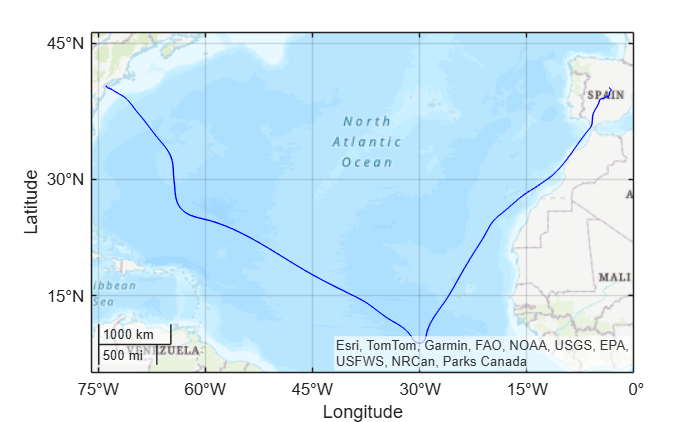

geoplot(LLA(:,1), LLA(:,2), "b-")
geolimits([10,42],[-76,0]);
geobasemap topographic;

Add the aircraft to the scenario using the [`platform`](docid:satcom_ref#mw_31a459a2-269e-4b33-977a-b6d51f2d9dd5) function. The `platform` function allows you to add platforms, such as aircraft, cars, or ships, to the scenario and perform access analysis with satellites, ground stations, and other platforms. Use the `Visual3DModel` property to add a visual representation of the aircraft to the scenario. For this example, use the NarrowBodyAirliner`.glb` file.

aircraft = platform(sc,trajectory, Name="Aircraft", Visual3DModel="NarrowBodyAirliner.glb");
%camtarget(viewer,aircraft);

### Satellites

Incluir los satélites de la constelación Startical:

- 320 satélites con 32 satélites cada plano

- 9 planos polares y 1 plano ecuatorial

- Órbitas circulares a 650 km de altura

- Satélites equiespaciados en la órbita

%% Create a satellite scenario object
NOS =   320;                 % Number of Satellites
NO  =   10;                  % Number of Orbits
NSPO=   NOS/NO;              % Number of Satellites per Orbit

H   =   650000;                                 % Orbit height [m]
RT  =   6371000;                                % Earth´s radious [m]
RA  =   (RT+H)*ones(NOS, 1);                    % Radius at the aphelium [m]
EXC =   0*ones(NOS, 1);                         % Excentricity    
INC =   [0*ones(NSPO, 1); 90*ones(NOS-NSPO, 1)];% Orbit inclination [º]
AOP =   0*ones(NOS, 1);                         % Argument of Periapsis [º] (ángulo en el plano de la órbita desde el nodo ascendente en el ecuador hasta el perigeo)

RAAN = reshape(repmat([0, 0, 20.56999969, 41.13999939, 61.70999908, 82.29000092, 102.9000015, 123.4000015, 144, 164.6000061], [NSPO, 1]), [1, NOS])';
                                                % Right Ascension of Ascending Node [º] (longitud del nodo ascendete en el plano ecuatorial)
TA = xlsread('faseSatsStartical.xlsx');
                                                % True Anomaly [º] (ángulo en el plano de la órbita desde el perigeo hasta el satélite)

% satellite(scenario,semimajoraxis,eccentricity,inclination,RAAN,argofperiapsis,trueanomaly)
sats = satellite(sc, RA, EXC, INC, RAAN, AOP, TA);
S = [ RA, EXC, INC, RAAN, AOP, TA ];

% Incorporar conos de visión al satélite
sensors = conicalSensor(sats, MaxViewAngle=120);
fieldOfView(sensors);

% play the scenario in the Satellite Viewer
%play(sc);

## Aircraft Access Analysis

Determine access analysis between the aircraft, airports, and satellites using the scenario. Calculate the access interval between the aircraft and airports using the [access](docid:satcom_ref#mw_aeb231b0-be89-4f06-a15d-9628350a5fc6) and [accessIntervals](docid:satcom_ref#mw_2b564569-fdb8-447e-9055-fba4fde2bdc9) functions based on when the aircraft has line-of-sight access to the airport. JFK and L.F. Wade airports can see the aircraft during the first and last two hours of the flight, respectively. Otherwise the aircraft is blocked by the curvature of the Earth.

%acAirport = access(aircraft,sc.GroundStations);
%airportAccessIntvls = accessIntervals(acAirport)

Calculate a similar access analysis between the aircraft and the satellites based on the visibility of the aircraft within the conical sensors' field of view. This serves as a first-round approximation of the Iridium multi-beam antenna shown in the next section. The dashed lines in the viewer show the line-of-sight access from the aircraft body to the airports and satellites.

acSatellite = access(aircraft, sensors);
satelliteAccessIntvls = accessIntervals(acSatellite);

Calcular el porcentaje de tiempo que hay X satélites a la vista

s = accessStatus(acSatellite);      % Tabla booleana de acceso: filas (sats) y columnas (timeSamples)
ss = sum(s,1);                      % Vector booleano de nº de sats a la vista para cada timeStamp
index = unique(ss);
for i=1:length(index)
    count(i) = sum(ss == index(i));
end
percentages = count/length(ss)*100;

Error using count
Not enough input arguments.


bar(percentages,'stacked');
xlabel('Número de satélites a la vista')
ylabel('% tiempo');
grid on;
title('Histrograma del número de satélites a la vista durante es escenario simulado')

[sSatellite,time] = accessStatus(acSatellite); 
satVisPlotData = double(sSatellite);
satVisPlotData(satVisPlotData == false) = NaN; % Hide invisible satellites.
satVisPlotData = satVisPlotData + (0:numel(sats)-1)'; % Add space to satellites to be stacked.

plot(time,satVisPlotData," .",Color="blue")
yticks(1:20:320)
yticklabels(sats.Name(1:20:320))
title("Visibilidad satélites")
grid on
xlabel("Tiempo de simulación")
axis tight

The access intervals computation shows that the aircraft has continuous satellite communication access with the Iridium network when the aircraft is over the open ocean. Combined with the airport access, the aircraft has continuous line-of-sight access throughout the flight.

## Determine Elevation Angles of Satellites with Respect to Ground Stations

Determine the elevation angle of each satellite with respect to source and target ground stations corresponding to `StartTime`. Accordingly, use `advance` to simulate the scenario for the first time step, namely, `StartTime`. Following this, use `aer` to retrieve the elevation angle of each satellite with respect to the ground stations. Assume that for the initial routing, the elevation angle of the first satellite in the path with respect to "Source Ground Station" and the last satellite in the path with respect to "Target Ground Station" must be at least 30 degrees. Accordingly, determine the elevation angles that are greater than or equal to this value.

% Calculate the scenario state corresponding to StartTime.
advance(sc);

% Retrieve the elevation angle of each satellite with respect to the ground
% stations.
gsSource = aircraft;
gsTarget = airports(2);
sat = sats;
[~,elSourceToSat] = aer(gsSource,sat);
[~,elTargetToSat] = aer(gsTarget,sat);


%% Determine the elevation angles that are greater than or equal to 30
% degrees.
elSourceToSatGreaterThanOrEqual30 = (elSourceToSat >= 20)';
elTargetToSatGreaterThanOrEqual30 = (elTargetToSat >= 30)';

## Determine Best Satellite for Initial Access to Constellation

The best satellite to be used for the initial access to the large constellation is assumed to be the one that satisfies the following simultaneously:

- Has the closest range to "Target Ground Station".

- Has an elevation angle of at least 30 degrees with respect to "Source Ground Station".

% Find the indices of the elements of elSourceToSatGreaterThanOrEqual30
% whose value is true.
trueID = find(elSourceToSatGreaterThanOrEqual30 == true);

% These indices are essentially the indices of satellites in sat whose
% elevation angle with respect to "Source Ground Station" is at least 30
% degrees. Determine the range of these satellites to "Target Ground
% Station".
[~,~,r] = aer(sat(trueID), gsTarget);

Index exceeds the number of array elements. Index must not exceed 320.

Error in ()


% Determine the index of the element in r bearing the minimum value.
[~,minRangeID] = min(r);

% Determine the element in trueID at the index minRangeID.
id = trueID(minRangeID);

% This is the index of the best satellite for initial access to the
% constellation. This will be the first hop in the path. Initialize a
% variable 'node' that stores the first two nodes of the routing - namely,
% "Source Ground Station" and the best satellite for initial constellation
% access.
nodes = {gsSource sat(id)};

## Determine Remaining Nodes in Path to Target Ground Station

The remaining nodes in the path are determined using a similar logic as what was used for determining the first satellite. If the elevation angle of the satellite in the current node is already at least 30 degrees with respect to "Target Ground Station", the next node is "Target Ground Station", thereby completing the path. Otherwise, the next node in the constellation is chosen using a logic that is similar to what was used for determining the first satellite in the path. The next node is the one that simultaneously satisfies the following:

- Has the closest range to "Target Ground Station".

- Elevation angle with respect to the satellite in the current node is greater than or equal to -15 degrees.

The elevation value of -15 degrees is chosen because the horizon with respect to each satellite in the constellation is about -21.9813 degrees. This value can be derived by assuming a spherical Earth geometry and the fact that these satellites are in near-circular orbits at an altitude of roughly 500 kilometers. Note that the spherical Earth assumption is used only for computing the elevation angle of the horizon below. The satellite scenario simulation itself assumes a WGS84 ellipsoid model for the Earth.

earthRadius = 6378137;                                                   % meters
altitude = 500000;                                                       % meters
horizonElevationAngle = asind(earthRadius/(earthRadius + altitude)) - 90 % degrees

horizonElevationAngle = -21.9813

Any satellite whose elevation angle with respect to another satellite is greater than -21.9813 degrees is guaranteed to be visible to the latter. However, choosing -15 degrees provides an adequate margin.

The subsequent nodes are continually added to the path until reaching a satellite whose elevation angle with respect to "Target Ground Station" is at least 30 degrees. After this, the final node is "Target Ground Station" itself, and the routing is complete.

% Minimum elevation angle of satellite nodes with respect to the prior
% node.
minSatElevation = -15; % degrees

% Flag to specify if the complete multi-hop path has been found.
pathFound = false;

% Determine nodes of the path in a loop. Exit the loop once the complete
% multi-hop path has been found.
while ~pathFound
    % Index of the satellite in sat corresponding to current node is
    % updated to the value calculated as index for the next node in the
    % prior loop iteration. Essentially, the satellite in the next node in
    % prior iteration becomes the satellite in the current node in this
    % iteration.
    idCurrent = id;

    % This is the index of the element in elTargetToSatGreaterThanOrEqual30
    % tells if the elevation angle of this satellite is at least 30 degrees
    % with respect to "Target Ground Station". If this element is true, the
    % routing is complete, and the next node is the target ground station.
    if elTargetToSatGreaterThanOrEqual30(idCurrent)
        nodes = {nodes{:} gsTarget}; %#ok<CCAT> 
        pathFound = true;
        continue
    end

    % If the element is false, the path is not complete yet. The next node
    % in the path must be determined from the constellation. Determine
    % which satellites have elevation angle that is greater than or equal
    % to -15 degrees with respect to the current node. To do this, first
    % determine the elevation angle of each satellite with respect to the
    % current node.
    [~,els] = aer(sat(idCurrent),sat); 

    % Overwrite the elevation angle of the satellite with respect to itself
    % to be -90 degrees to ensure it does not get re-selected as the next
    % node.
    els(idCurrent) = -90; 

    % Determine the elevation angles that are greater than or equal to -15
    % degrees.
    s = els >= minSatElevation;

    % Find the indices of the elements in s whose value is true.
    trueID = find(s == true);

    % These indices are essentially the indices of satellites in sat whose
    % elevation angle with respect to the current node is greater than or
    % equal to -15 degrees. Determine the range of these satellites to
    % "Target Ground Station".
    [~,~,r] = aer(sat(trueID), gsTarget);

    % Determine the index of the element in r bearing the minimum value.
    [~,minRangeID] = min(r);

    % Determine the element in trueID at the index minRangeID.
    id = trueID(minRangeID);

    % This is the index of the best satellite among those in sat to be used
    % for the next node in the path. Append this satellite to the 'nodes'
    % variable.
    nodes = {nodes{:} sat(id)}; %#ok<CCAT>
end

Index exceeds the number of array elements. Index must not exceed 320.

Error in ()

## **Determine Intervals When Calculated Path Can Be Used**

We must now determine the intervals over the next 3 hours during which calculated path can be used. To accomplish this, manually stepping through each time step of the scenario is not necessary. Instead, we can make the scenario auto-simulate from `StartTime` to `StopTime`. Therefore, set `AutoSimulate` of the scenario to `true`.

sc.AutoSimulate = true;

Add an access analysis with the calculated nodes in the path. Set `LineColor` of the access visualization to red.

ac = access(nodes{:});
ac.LineColor = "red";

Determine the access intervals using the `accessIntervals` function. Since `AutoSimulate` has been set to `true`, the scenario will automatically simulate from `StartTime` to `StopTime` at the specified `SampleTime` before calculating the access intervals.These intervals are the times when the calculated multi-hop path can be used.

intvls = accessIntervals(ac)

intvls = 2×8 table
      Source                 Target                IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    __________    _____________________________    ______________    ____________________    ____________________    ________    __________    ________

    "Aircraft"    "LEMD Adolfo Suárez (Madrid)"          1           14-Apr-2026 11:10:00    14-Apr-2026 11:15:00      300          NaN          NaN   
    "Aircraft"    "LEMD Adolfo Suárez (Madrid)"          2           14-Apr-2026 12:47:00    14-Apr-2026 12:49:00      120          NaN          NaN   


## Visualize Path

Launch the satellite scenario viewer with `ShowDetails` set to `false`. When the `ShowDetails `property is set to `false`, only satellites and ground stations will be shown. Labels and orbits will be hidden. Mouse over satellites and ground stations to show their labels.The green lines represent the multi-hop path. Also, set `MarkerSize` of the satellites to 6 to further declutter the visualization. Set the camera position to 60 degrees latitude and 5 degrees longitude to bring the multi-hop path into view..

v = satelliteScenarioViewer(sc,"ShowDetails",false);
sat.MarkerSize = 6; % Pixels
campos(v,60,5);     % Latitude and longitude in degrees